# 输入数据

wine_table = readtable('wine.csv');

featuresNames = {'Alcohol', 'Malic_acid', 'Ash', 'Alcalinity_of_ash', ...
    'Magnesium', 'Total_phenols', 'Flavanoids', 'Nonflavanoid_phenols', ...
    'Proanthocyanins', 'Color_intensity', 'Hue', ...
    'OD280OD315_of_diluted_wines', 'Proline'};
features = wine_table(:, featuresNames);
label = wine_table.Class;

# 线性判别分析

留出法验证

model = fitcdiscr(features, label, 'Holdout' , .15);
classifier = model.Trained{1};
test = model.Partition.test;
testsize = model.Partition.TestSize;
accuracy = sum(classifier.predict(features(test, :)) == label(test))/testsize;
display(accuracy)

accuracy = 1

交叉验证

model = fitcdiscr(features, label, 'Kfold', 10);
accuracy = 1 - model.kfoldLoss;
display(accuracy)

accuracy = 0.9831

# 决策树分类

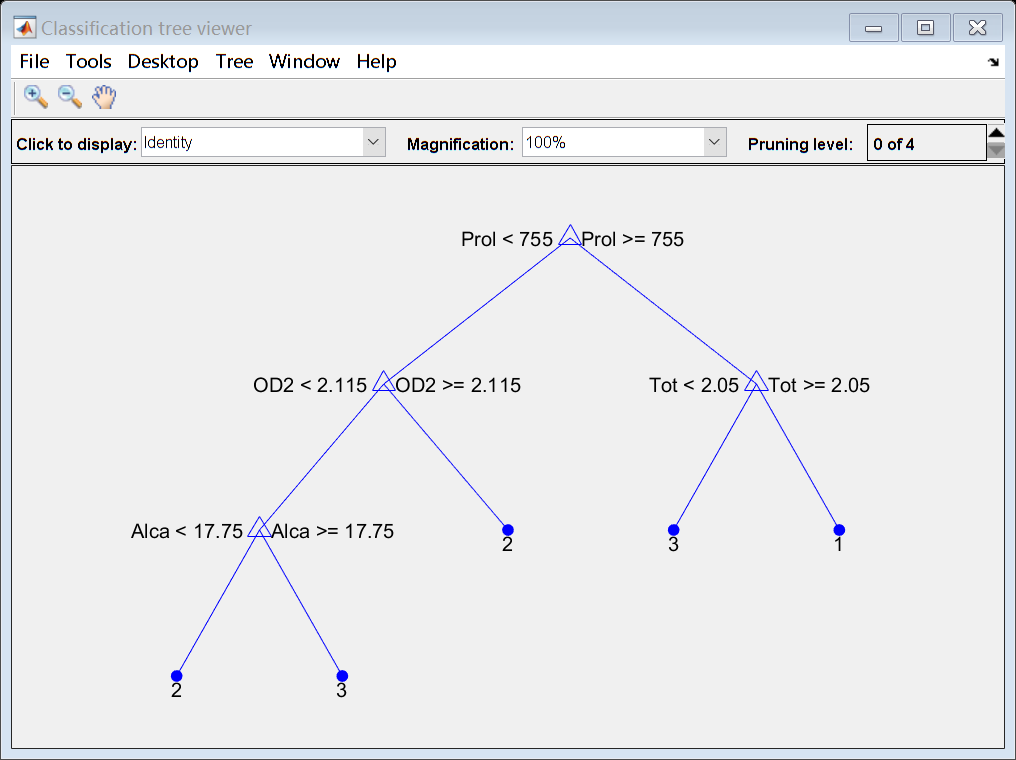

features.Properties.VariableNames = {'Alco', 'Mali', 'Ash', 'Alca', ...
    'Mag', 'Tot', 'Fla', 'Nonf', 'Proa', 'Col', 'Hue', 'OD2', 'Prol'};
tree = fitctree(features, label, 'KFold', 10, 'MinLeafSize', 5);
view(tree.Trained{1}, 'mode', 'graph')

tree.Trained{1}.NodeSize(tree.Trained{1}.IsBranchNode);    % 分支点的实例数

ans =    161
   100
    61
    42


tree.Trained{1}.NodeSize(~tree.Trained{1}.IsBranchNode);   % 叶子节点的实例数

ans =     58
     6
    55
     5
    37


tree.Trained{1}.NodeError(~tree.Trained{1}.IsBranchNode);  % 叶子节点错误率

ans =     0.0502
    0.1712
    0.0375
    0.1948
    0.0279


accuracy = 1 - tree.kfoldLoss

accuracy = 0.9101

看看结点变量的区分度

featuresNames = {'Color_intensity', 'Flavanoids', 'Proline'};
arrFeat = table2array(features(:, featuresNames));

Unrecognized variable name 'Color_intensity'.

gplotmatrix(arrFeat,arrFeat,label)

# PCA 可视化

arrFeatures = table2array(features);
Z = zscore(arrFeatures);
[coefs,score,latent] = pca(Z);
accum = zeros(size(latent,1),1);
for i = 1:size(latent,1)
    accum(i) = sum(latent(1:i))/sum(latent);
end
stairs(accum)
grid on

shortNames = ["Alco" "Mali" "Ash" "Alca"...
    "Mag" "Tot" "Fla" "Nonf" "Proa" "Col" "Hue" "OD2" "Prol"]';
Corr = corr(arrFeatures);
f = heatmap(Corr);
title("correlation of each feature")

